# Lead-lag compensator design with Bode diagrams

This live script needs the control toolbox. Once profficient, students will probably find that the methods used in this script are mostly performed using sisotool. 

The script goes through the main principles of a mechanistic lead-lag design, that is directly linked to criteria, and followed by a number of worked examples.

We also assume the students are already comfortable with the design procedures in the files: **lead_design_with_bode.mlx and lag_design_with_bode.mlx**

Users might also like to see  the app: ***lead_lag_design_phase_margin***.***mlapp*** which is part of the toolbox and automates much of the illustrations shown in the code below so users can focus on steps and concepts rather than coding.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help Control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Lead and Lag compensator reminders

- Example of a simple lead-lag design using phase margin, bandwidth and low frequency gain criteria

- Check the final design

- Design with a system containing no integrator

- Further example lead-lag design

- Virtual laboratory: ***lead_lag_design_phase_margin***.***mlapp***

- Subfunction bodechange.m

## 1. Technical and mathematical background

This script assumes the following block diagram with system *G(s)* and compensator *M(s)*. The focus here is on a simple lead-lag design approach for *M(s)* based on design criteria or specifications.

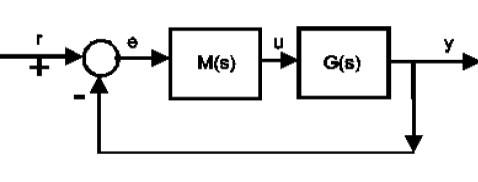

## 2. Lead and Lag compensator reminders

The lead compensator is given as follows and is based on the two criteria: desired PM $\phi$ and desired bandwidth $w_c$ (cross over frequency). The offset is a consequence of  these two criteria and not managed. The full design process is in the file **lead_design_with_bode.mlx**

$\;M\left(s\right)$$=K\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$;        $1\le r\le 10$   

A lag compensator is based on the two criteria: desired PM $\phi$ and desired low frequency gain (typically a ramp error offset). The cross-over frequency $w_c$ falls out automatically from these two criteria. The full design process is in the file **lag_design_with_bode.mlx**

$M\left(s\right)\;=\;\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10p}}\right)$ ;                    $1\le p\le 10$.

### 2.1 Why lead-lag compensator design?

Both lead and lag can satisfy only 2 criteria, and ignore the 3rd whereas typically there are 3 common criteria:

- phase margin (equivalently damping).

- offset.

- bandwidth/cross-over frequency .

By combining lead and lag, we add an additional degree of freedom (3 parameters* K, p, r*) and thus can meet all 3 criteria (assuming these are set sensibly).


$$M\left(s\right)\;=\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10p}}\right)$$

$$\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$$


### 2.2 Fundamental approach to lead-lag design

- First use a standard lead design to meet the bandwidth $w_c$ and PM $\phi$requirements. This sets the parameters ***K*** and ***r***.

- Second, add a lag component to improve the low frequency gain. Rather than being too fussy about a specific ramp or step error constant, in this file we can talk about how much gain recovery is wanted; this is given by parameter ***p***. [Further details on step and ramp error offsets are in the file **lag_design_with_bode.mlx **and summarised below.] 

**Notes on gain recovery from lag component: Note do the lead design first so only p is to be determined!**

**Ramps:  **Find the ramp error offset  $e_{\textrm{ramp}} =\lim_{s\longrightarrow 0} \frac{1}{\textrm{sG}\left(s\right)M\left(s\right)};\;\;\;\;M\left(0\right)=\frac{\textrm{Kp}}{r}$

Let  $\lim_{s\longrightarrow 0} \textrm{sG}\left(s\right)=\alpha$, then:    $e_{\textrm{ramp}} =\frac{r}{\alpha \textrm{Kp}}$$\;\;\;\Rightarrow \;\;p=\frac{r}{\alpha Ke_{\textrm{ramp}} }$

**Offset to steps**: The offset is given by the formulae: $e_{\textrm{ss}} =\frac{1}{1+G\left(0\right)M\left(0\right)}=\frac{1}{1+G\left(0\right)\frac{\textrm{Kp}}{r}}$

To get a specified offset the required value for ***p*** is: $p=\frac{r}{\textrm{KG}\left(0\right)}\left(\frac{1}{e_{\textrm{ss}} }-1\right)$.

## 3. Example of a simple lead-lag design using phase margin, bandwidth and low frequency gain criteria 

For this section, assume the system includes an integrator so that the offset to constant targets is zero. We want to design the parameters of the compensator M(s) so that we have a desirable phase margin, bandwidth and low frequency gain. The process can be systemised as follows into several key steps.

**STEP 1:** Specify the system and desired **CRITERIA**:  phase margin $\phi$ (equivalently damping ratio - see section 1a),  desired bandwidth (gain cross over frequency) $w_c$ and low frequency gain recovery ***p***.  If these turn out to be poor or unreasonable choices it will be evident following the later design steps.

G=tf(1,[1 5 8 0]);
wc=2; % target cross over freq
desiredPM = 60; % target PM
gainrecovery=5; % desired gain recovery from lag component
[gainGwc,phaseGwc] = bode(G,wc);

wmin=0.01;
wmax=6;
figure; clf
bode(G,{wmin,wmax});grid;hold on
plot([wmin,wmax],[-180+desiredPM]*[1 1],'r')
text(wmin*10,-180+desiredPM+10,'-180+\phi')
plot([wc,wc],[-180+desiredPM,-90],'g','linewidth',3)
text(wc*1.1,-180+desiredPM+15,'wc')


**STEP 2:** Determine how much phase change $\theta$ is required so that $\arg \left(G\left(jw_c \right)M\left(jw_c \right)\right)=-180+\phi$. Assume that $\arg \left(M\left(jw_c \right)\right)=\theta$  so this reduces to:  $\theta =-\arg \left(G\left(jw_c \right)\right)-180+\phi$ hence $\theta$ is required uplift at the gain cross over frequency $w_c$ to achieve the target PM. You need to ensure the required uplift is between about 10 and 55 degrees, or the required pole/zero ratio will be outside of bounds. **If the required uplift is too large, the desired bandwidth will need reducing.**

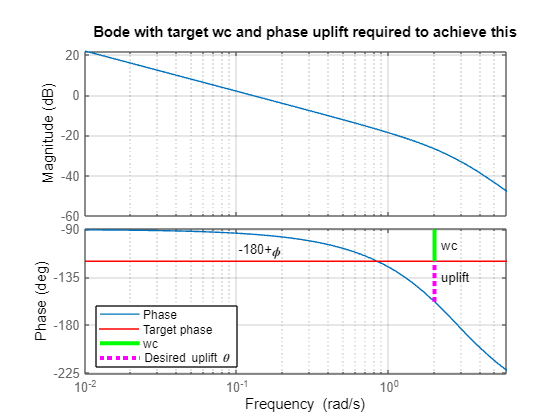

uplift = -180 - phaseGwc +desiredPM;
plot([wc,wc],[phaseGwc,-180+desiredPM],'m:','linewidth',3)
text(wc*1.1,-180+desiredPM-15,'uplift')
legend('Phase','Target phase','wc','Desired uplift \theta','Location','Southwest')
title('Bode with target wc and phase uplift required to achieve this')

disp('*****************************************')

*****************************************


disp(['Identified a suitable uplift as ',num2str(uplift),'deg'])

Identified a suitable uplift as 38.1986deg


**STEP 3:** Determine the required pole/zero ratio* r* from: $\;\;\;r=\frac{\sin \left(\theta \right)+1}{1-\sin \left(\theta \right)}$.  Again a reminder that this should be within the bounds $1\le r\le 10$ and if not, the bandwidth and/or PM criteria will need to be relaxed.

disp('*****************************************')

*****************************************


disp('Pole/zero ratio')

Pole/zero ratio


upliftrad=uplift*pi/180;
r = (sin(upliftrad)+1)/(1-sin(upliftrad))

r = 4.2409

**STEP 4:** Determine the proportional term required to ensure the bandwidth requirement is met, that is: $\;K=\frac{\sqrt{r}}{\left|G\left(jw_c \right)\right|}$ . The figure should show that the desired cross-over frequency has been achieved, that is the magenta (0dB) and green ($w_c$)  intersection should also lie on the compensated gain plot. Use all these parameters (*K,r*,$w_c$) from steps 1-4 in the formula for the lead component.


$$M\left(s\right)$$

$$=K\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$$


sr=sqrt(r);
K= sr/gainGwc

K = 44.3598

zero = wc/sr;
pole = wc*sr;
disp('Final compensator');

Final compensator


Mlead = K*tf([1,zero],[1,pole])

Mlead =
 
  44.36 s + 43.08
  ---------------
     s + 4.119
 
Continuous-time transfer function.



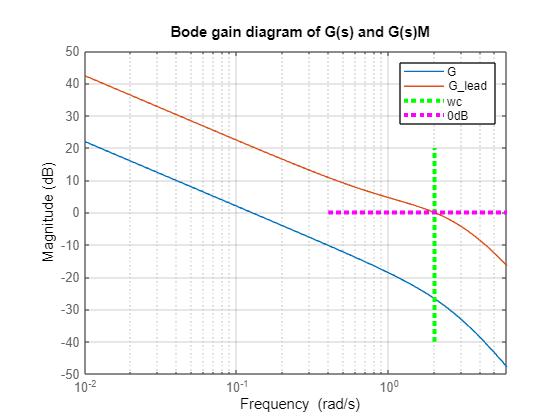


figure; clf
bodemag(G,G*Mlead,{wmin,wmax});grid;hold on
plot([wc,wc],[-40,20],'g:','linewidth',3)
plot([wc/5,wc*5],[0,0],'m:','linewidth',3)
title(['Bode gain diagram of G(s) and G(s)M'])
legend('G','G_lead','wc','0dB')

**STEP 5**: Recover low frequency gain using the lag component which has a single unknown parameter *p*. Here for simplicity of illustrration we set the gain recovery to be p=5.


$$\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10p}}\right)$$


p=gainrecovery

p = 5

Mlag = tf([1,wc/10],[1,wc/(p*10)])

Mlag =
 
  s + 0.2
  --------
  s + 0.04
 
Continuous-time transfer function.



## 4. Check the final design

You should ensure that the phase margins and bandwidth criteria have been met and also that pole/zero ratio is within sensible limits.

If the design is correct, you would expect the compensated system to have:

- A PM similar  to the target PM (likely a few degrees worse due to the negative phase from the lag component).

- A cross over frequency similar to the one specified.

- The phase lift around the cross-over frequency should be evident when one overlays the compensated and uncompensated plots.

- The increase in low frequency gain offered by the lag component will be evident in overlay plots (with and without the lag component), as well as the consequent phase dip well to the left of the cross over frequency.

disp('******************************************************')

******************************************************


disp('CHECK MARGINS OF FINAL DESIGN')

CHECK MARGINS OF FINAL DESIGN


disp(['Target phase margin was ',num2str(desiredPM)])

Target phase margin was 60


disp(['Target cross-over frequency was ',num2str(wc)])

Target cross-over frequency was 2


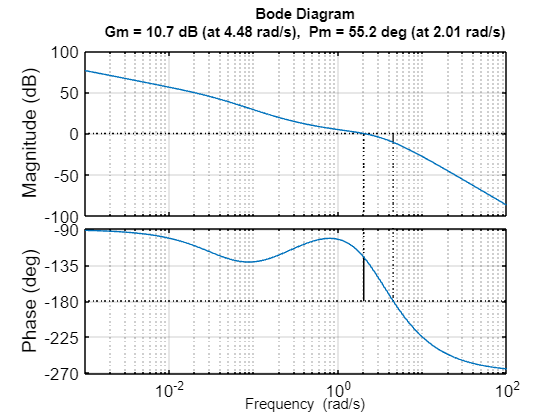

figure; clf
margin(G*Mlead*Mlag)
grid
bodechange

disp('*****************************************')

*****************************************


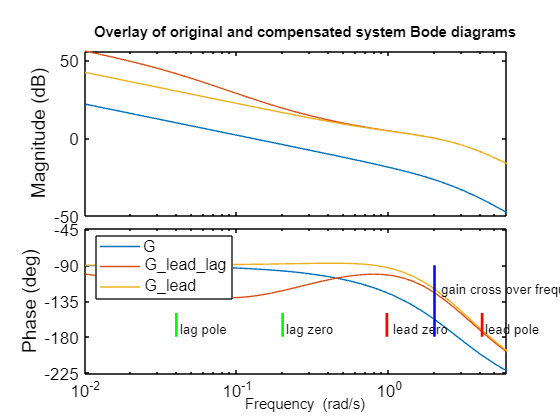

figure; clf
bode(G, G*Mlead*Mlag, G*Mlead,{wmin,wmax});grid; hold on
bodechange

plot([pole,pole],[-180,-150],'r-','linewidth',2)
text(pole*1.05,-170,'lead pole')
plot([zero,zero],[-180,-150],'r-','linewidth',2)
text(zero*1.1,-170,'lead zero')
plot(wc/(10*p)*[1,1],[-180,-150],'g-','linewidth',2)
text(wc*1.05/(10*p),-170,'lag pole')
plot((wc/10)*[1,1],[-180,-150],'g-','linewidth',2)
text(1.05*wc/10,-170,'lag zero')
plot([wc,wc],[-180,-90],'b-','linewidth',2)
text(wc*1.1,-120,'gain cross over frequency')
legend('G','G_lead_lag','G_lead','Location','Northwest')
title('Overlay of original and compensated system Bode diagrams')

bodechange

#### Step responses and overlay with lead, lag and lead-lag designs

Step responses are included below for completeness. We have also overlaid this with the alternative of a lag-only design. It is clear that the lag only design is much slower (lower bandwidth), but therefore also uses a much less aggressive input.

disp('BELOW are step responses')

BELOW are step responses


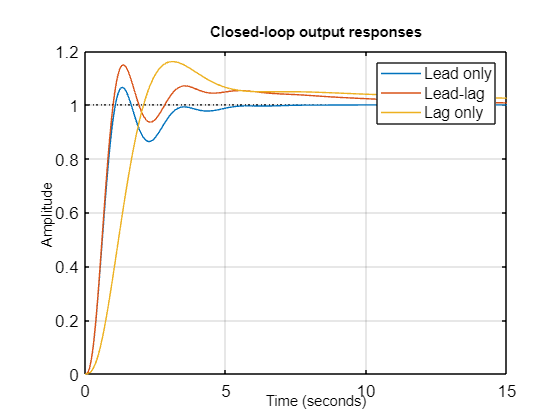


figure;clf
Mlagonly = tf([7.16 0.61],[1,0.015]);  %% see file lag_design_with_bode.mlx for details
GcMlead=feedback(G*Mlead,1);
GcMleadlag=feedback(G*Mlead*Mlag,1);
GcMlagonly=feedback(G*Mlagonly,1);
step(GcMlead,GcMleadlag,GcMlagonly,15);
title('Closed-loop output responses')
legend('Lead only','Lead-lag','Lag only')
grid
bodechange

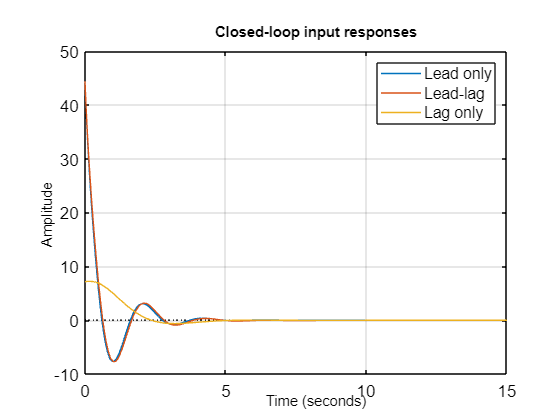


figure;clf
GcMleadu=feedback(Mlead,G);
GcMleadlagu=feedback(Mlead*Mlag,G);
GcMlagonlyu=feedback(Mlagonly,G);
step(GcMleadu,GcMleadlagu,GcMlagonlyu,15);
title('Closed-loop input responses')
legend('Lead only','Lead-lag','Lag only')
grid
bodechange

## 5. Design with a system containing no integrator

The following code is given without further comment as the in line comments should be sufficient to link to all the previous materials. Here the designs are based on offset to a step.

disp('BELOW is SECTION 5: System with no integrator')

BELOW is SECTION 5: System with no integrator




% System and requirements
G=tf(1,[1 2 0.4]);
G0=dcgain(G);
offset = 0.03; % target offset
PM =60; % target phase margin
wc=3.6; % target bandwidth

% proportional design
disp('************************************')

************************************


disp('Proportional design - PM criteria only')

Proportional design - PM criteria only


Kp = 3.3

Kp = 3.3000

wc1 = 1.43

wc1 = 1.4300

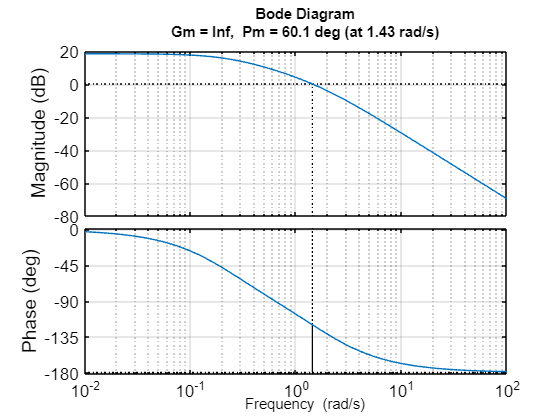

margin(G*Kp)
grid
bodechange

offset_Kp = 1/(1+(G0*Kp))

offset_Kp = 0.1081


% Lag design
disp('************************************')

************************************


disp('Lag design - PM and offset criteria')

Lag design - PM and offset criteria


p = (1/(G0*Kp))*((1/offset)-1)

p = 3.9192

Lag = Kp*tf([1,wc1/10],[1,wc1/(10*p)])

Lag =
 
  3.3 s + 0.4719
  --------------
   s + 0.03649
 
Continuous-time transfer function.



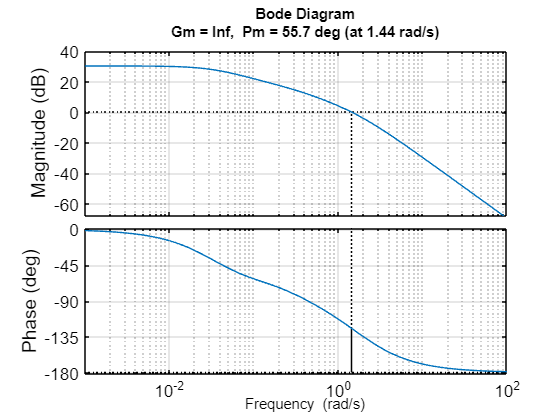

margin(G*Lag)
grid
bodechange

offset_lag =  1/(1+(G0*Kp*p))

offset_lag = 0.0300


% lead design
disp('************************************')

************************************


disp('Lead design - PM and bandwidth criteria')

Lead design - PM and bandwidth criteria


% for a cross over of 3, PM is 30 so phaselift =30;
upliftrad=30*pi/180;
r = (sin(upliftrad)+1)/(1-sin(upliftrad))

r = 3

sr=sqrt(r);
[gainGwc] = bode(G,wc); 
K= sr/gainGwc

K = 25.0755

Lead = K*tf([1,wc/sr],[1,wc*sr])

Lead =
 
  25.08 s + 52.12
  ---------------
     s + 6.235
 
Continuous-time transfer function.



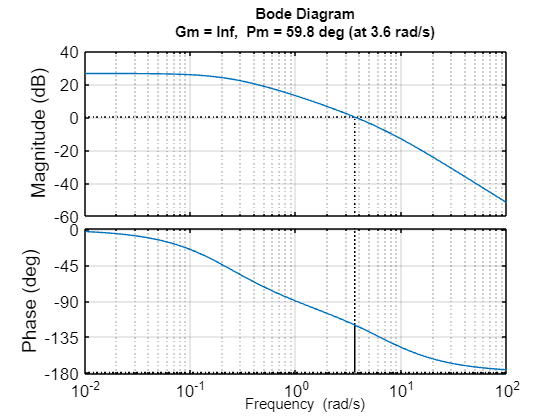

margin(G*Lead); grid
bodechange

offset_lead = 1/(1+(G0*K/r))

offset_lead = 0.0457


% Lead-lag design
disp('************************************')

************************************


disp('Lead-lag design - PM, offset and bandwidth criteria')

Lead-lag design - PM, offset and bandwidth criteria


p2=(r/(K*G0))*((1/offset)-1)

p2 = 1.5473

Lag2= tf([1,wc/10],[1,wc/(10*p2)])

Lag2 =
 
   s + 0.36
  ----------
  s + 0.2327
 
Continuous-time transfer function.



Leadlag= Lead*Lag2

Leadlag =
 
  25.08 s^2 + 61.15 s + 18.76
  ---------------------------
     s^2 + 6.468 s + 1.451
 
Continuous-time transfer function.



margin(G*Leadlag); grid
offset_lead_lag = 1/(1+(G0*K*p2/r))

offset_lead_lag = 0.0300

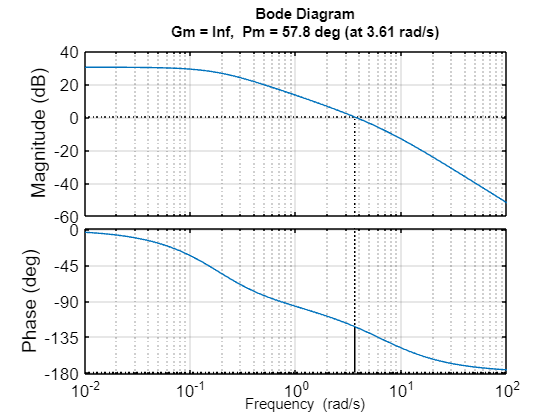

bodechange


% Compare all
disp('************************************')

************************************


disp('Compare all designs')

Compare all designs


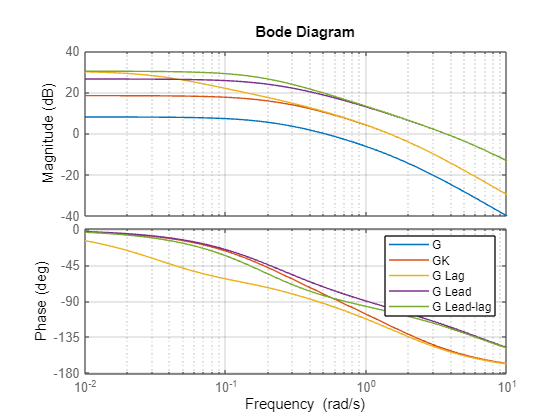

bode(G,G*Kp,G*Lag,G*Lead,G*Leadlag,{0.01,10});grid
legend('G','GK','G Lag', 'G Lead', 'G Lead-lag')

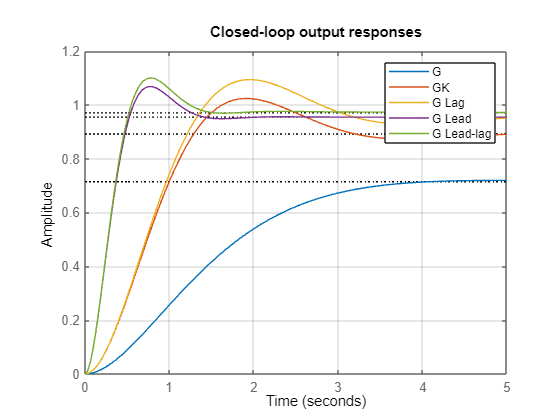

step(feedback(G,1),feedback(G*Kp,1),feedback(G*Lag,1),feedback(G*Lead,1),feedback(G*Leadlag,1),5)
legend('G','GK','G Lag', 'G Lead', 'G Lead-lag')
grid

title('Closed-loop output responses')

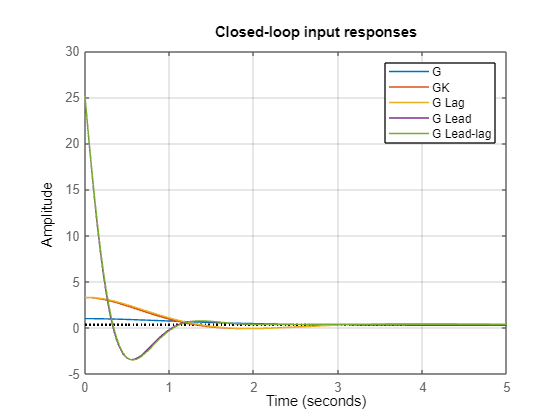

step(feedback(1,G),feedback(Kp,G),feedback(Lag,G),feedback(Lead,G),feedback(Leadlag,G),5)
legend('G','GK','G Lag', 'G Lead', 'G Lead-lag')
title('Closed-loop input responses')
grid

## 6. Further example lead-lag design

disp('BELOW is SECTION 6')

BELOW is SECTION 6




% System and requirements
G=tf([1 10],poly([0 -1 -2 -3]));
G2 = tf([1 10],poly([-1 -2 -3]));
wc = 0.9; % bandwidth
desiredPM=60; % PM
Kvdesired =5; % ramp error constant

% lead to meet bandwidth and PM requirements
%%% find gain to give bandwidth = 1.9 and thus required phase rotation
[gain,phase]=bode(G,wc);
K=1/gain

K = 0.8284

currentPM= 180+phase;
Protate = (desiredPM-currentPM)*pi/180;
beta = (1+sin(Protate))/(1-sin(Protate))

beta = 6.7062

Klead = tf(K*sqrt(beta)*[1,wc/sqrt(beta)],[1,wc*sqrt(beta)])

Klead =
 
  2.145 s + 0.7456
  ----------------
     s + 2.331
 
Continuous-time transfer function.
Model Properties



%% lag to meet low freq. gain requirements
% Ramp error computations (Offset to ramp is 1/Kv)
disp('Ramp error constants')

Ramp error constants


Kvlead= dcgain(G2)*dcgain(Klead)

Kvlead = 0.5331

r = Kvdesired/Kvlead

r = 9.3783

Klag = tf([1,wc/10],[1,wc/(10*r)])

Klag =
 
    s + 0.09
  ------------
  s + 0.009597
 
Continuous-time transfer function.
Model Properties


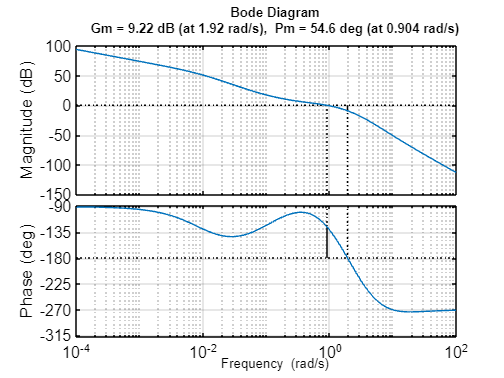


Ktotal=Klag*Klead;
figure(1);clf reset
margin(G*Ktotal)
grid
bodechange


disp('************************************')

************************************


disp('Compare Lead and Lead-lag')

Compare Lead and Lead-lag


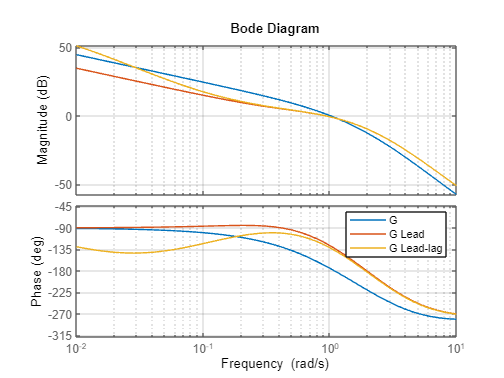

bode(G,G*Klead,G*Ktotal,{0.01,10});grid
legend('G','G Lead', 'G Lead-lag')

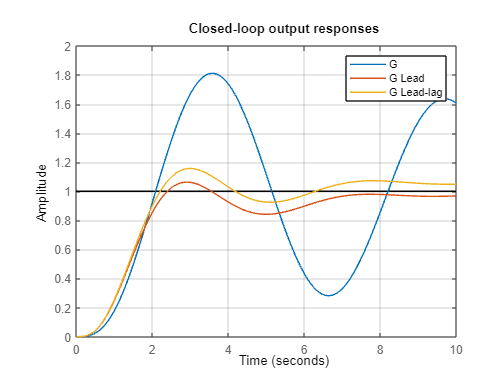

step(feedback(G,1),feedback(G*Klead,1),feedback(G*Ktotal,1),10)
legend('G','G Lead', 'G Lead-lag')
grid
title('Closed-loop output responses')

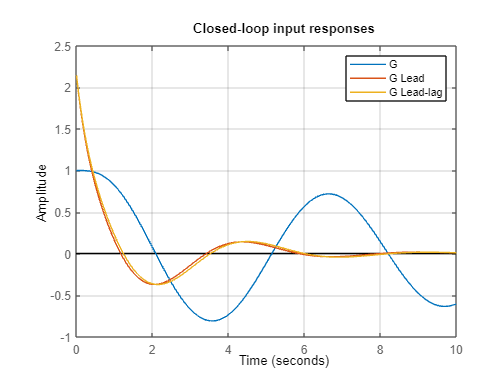

step(feedback(1,G),feedback(Klead,G),feedback(Ktotal,G),10)
legend('G', 'G Lead', 'G Lead-lag')
title('Closed-loop input responses')
grid

## 7. Virtual laboratory: ***lead_lag_design_phase_margin***.***mlapp***

A screen dump of the app is given here. This file is part of the control101 toolbox so should appear under the apps tab once you have downloaded the toolbox.

% lead_lag_design_phase_margin

The purpose of the app is to allow users to focus on concepts and learning rather than coding, whereas this livescript gives more focus on the mathematical and coding details. Hence the app allows users to carry out the design procedures above, but only on a predefined set of systems and to a relatively crude accuracy level.

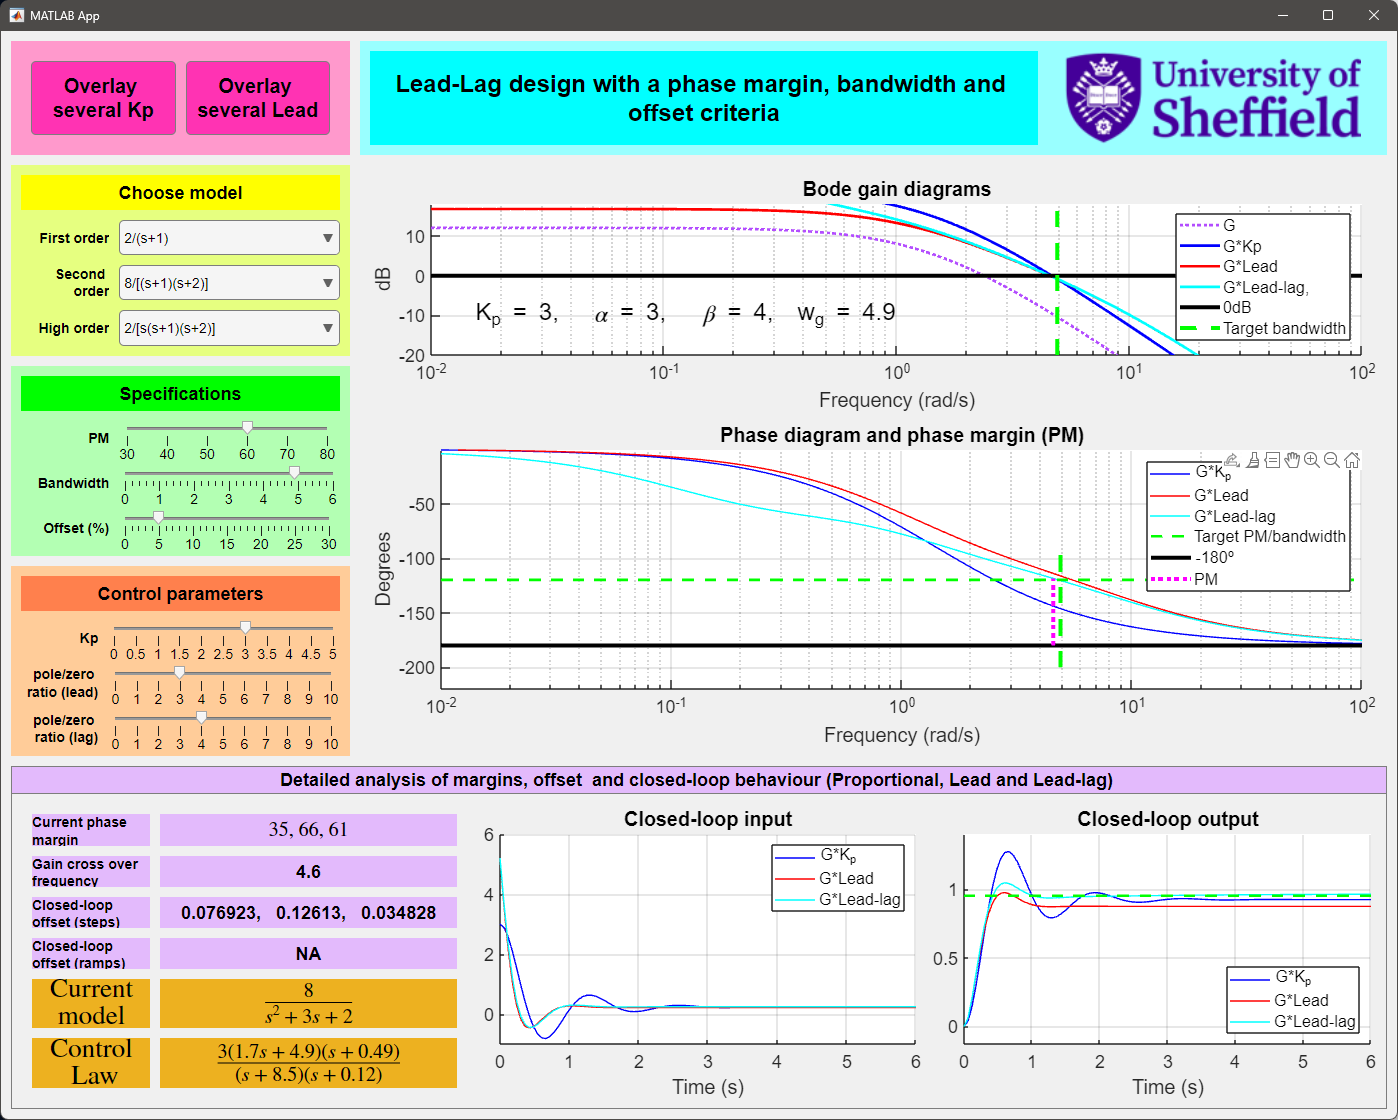

## 8. Subfunction bodechange.m

Used to make the axes and ticks bolder and larger.

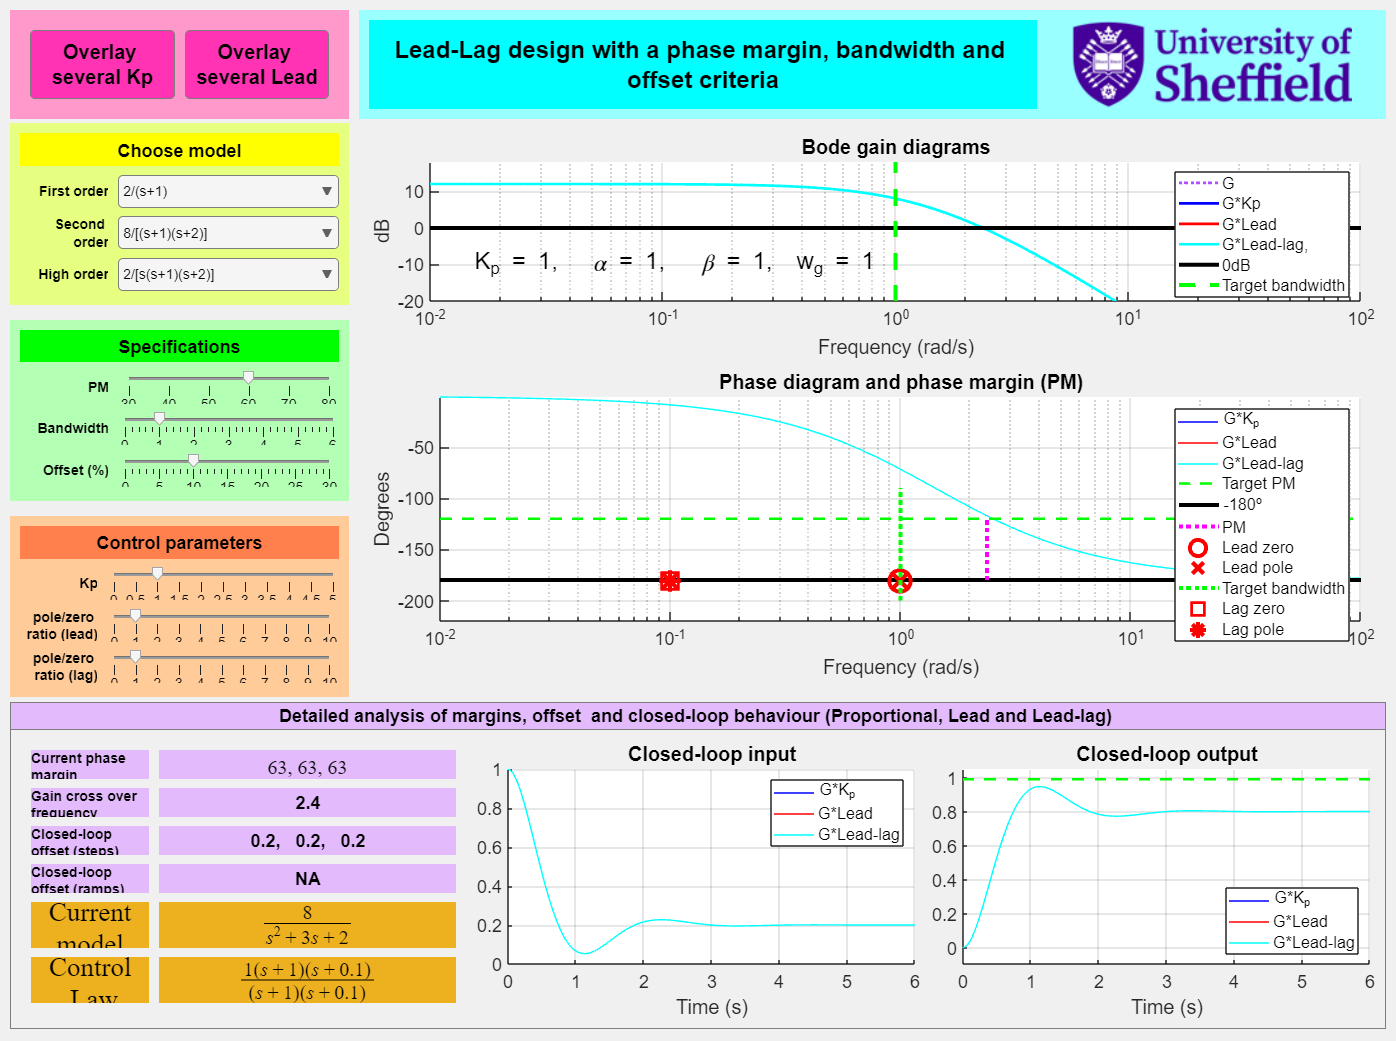

function bodechange


h=findobj(get(gcf, 'children'), 'Type', 'axes');

for i=1:length(h)
    set(h(i), 'fontSize', 13)
    set(h(i), 'XColor', [0 0 0])
     set(h(i), 'YColor', [0 0 0])
    
end

end
